% func = @(x) sin(x);                 % testovaná funkce
func = @(x) (2.*x.^2)+(-5.*x)+4;  
from = -10; %0;  
to = 10;    %2*pi; 

N =  20;                              % počet vzorků
x = from:((to-from)/(N-1)):to;           % vzorkovací čas
t = awgn(func(x),10);               % generátor naměřených dat
t = func(x);
x_c = from:((to-from)/((N*100)-1)):to;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh
M = 2;                              % řád polynomu

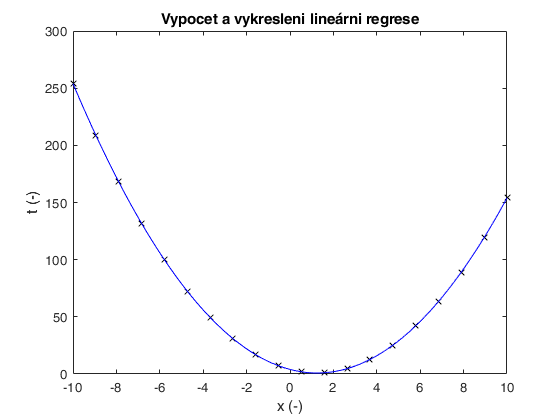

figure();
plot(x,t,'kx',x_c,t_c,'b');                     % vykreslení naměřených dat
title("Vypocet a vykresleni lineárni regrese");
xlabel("x (-)");
ylabel("t (-)")
hold on;

warning('off')                                  % zákaz vypisování warning zpráv

N = length(x);          % počet pozorování získaný z délky vektoru vstupních hodnot
t = t';                 % s maticí výstupů chci pracovat jako se sloupcovým vektorem
Phi = zeros(N,M+1);
for j = 0:M
    for i = 0:N-1
        Phi(i+1,j+1) = x(i+1)^j;
    end
end


% t = Phi*w
% w_a = Phi\t;

Phi = Phi(1:3,1:3);
t = t(1:3);

M = 2;
Phi = [4 -1 0;-1 4 -1;0 -1 4];
t = [2 6 2]';

w = zeros(M+1,1); % nastavení počátečního bodu do nuly (mohl bych nastavovat např. náhodně)

for i = 1:50
    % 1 rozdíl aproximace od naměřených dat
    r = t - Phi*w;
    % 2  
    alpha = (r'*r)/(r'*Phi*r);
    % 3
    w = w + alpha*r
    t_w = Polynomial_evaluation(x,w);
    plot(x,t_w,'r--');  
end

legend("Namerena trenovaci data","Puvodni krivka bez sumu", "Aproximacni krivka");